只考虑一阶模态

导入数据

clc;clear;close all
addpath("data\一阶1036\")
blockheight=234000/50;
damping_result=importdata('result0.mat');
for k1 = 1:50
    str="tempdata=importdata('result"+num2str(k1-1)+".mat');";
    eval(str)
    damping_result(blockheight*(k1-1)+1:blockheight*(k1),4:7)=tempdata(blockheight*(k1-1)+1:blockheight*(k1),4:7);
end

damping_result(:,8)=min(damping_result(:,6),damping_result(:,7));
Damping_result=array2table(damping_result,"VariableNames",["Frequency TMD","Damping Ratio","Mass Ratio","Frequency1","Frequency 2","Damping Ratio 1","Damping Ratio 2","Min Damping Ratio"]);

画图

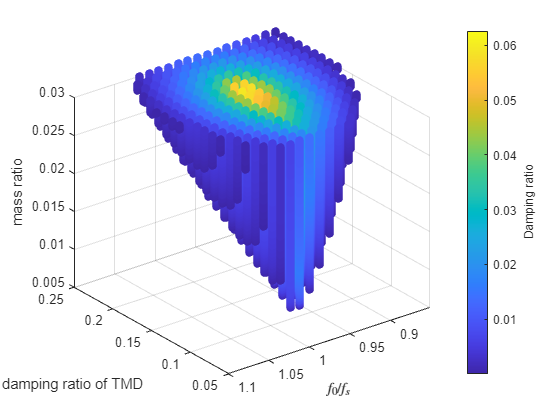

Damping_result_filter=Damping_result(Damping_result.("Min Damping Ratio")>0,:);
Damping_result_filter=Damping_result_filter(Damping_result_filter.("Mass Ratio")<=0.03,:);
Frequency = Damping_result_filter.("Frequency TMD");                              % longitude data
DampingRatio =Damping_result_filter.("Damping Ratio");                                % latitude data
MassRatio = Damping_result_filter.("Mass Ratio");                       % percent rural data
MinDampingRatio =Damping_result_filter.("Min Damping Ratio");                        % fatalities data
Fre0=0.833853594612216;
Damping_result_filter.("Fre_ratio")=Frequency./Fre0;
scatter3(Damping_result_filter.("Fre_ratio"),DampingRatio,MassRatio,40,MinDampingRatio,'filled')    % draw the scatter plot
ax = gca;
ax.XDir = 'reverse';
% view(-31,14)
xlabel('$f_0 / f_s$','Interpreter','latex')
ylabel('damping ratio of TMD')
zlabel('mass ratio')

cb = colorbar;                                     % create and label the colorbar
cb.Label.String = 'Damping ratio';

数据分析

[~,maxseq]=max(MinDampingRatio);%最大阻尼比对应参数
maxresult=Damping_result(maxseq,:);
idx=Damping_result.("Damping Ratio")<=0.1;
data_filter=Damping_result(idx,:);
idx=data_filter.("Mass Ratio")==0.015;
data_filter=data_filter(idx,:);
[~,maxseq2]=max(data_filter.("Min Damping Ratio"));%最大阻尼比对应参数
maxresult2=data_filter(maxseq2,:);
disp(maxresult2)

    Frequency TMD    Damping Ratio    Mass Ratio    Frequency1    Frequency 2    Damping Ratio 1    Damping Ratio 2    Min Damping Ratio
    _____________    _____________    __________    __________    ___________    _______________    _______________    _________________

        0.82              0.1           0.015        0.79111        0.86293         0.022497           0.029706            0.022497     




Damping_result_filter_data=table2array(Damping_result_filter);

save Dampingresult_filter_data_1036_1mode Damping_result_filter_data

最优TMD参数

mu=0.01;
Fre0=0.833853594612216;
f0=Fre0*(1+mu);
f0fs=1/(1+mu);
zeta=sqrt(3*mu/8/(1+mu));
disp(f0fs)

    0.9901



disp(zeta)

    0.0609



考虑二阶模态情况下

clc;clear;close all
addpath("data\二阶1036\")
blockheight=167400/50;
damping_result=importdata('result_2mode_0.mat');
for k1 = 1:50
    str="tempdata=importdata('result_2mode_"+num2str(k1-1)+".mat');";
    eval(str)
    damping_result(blockheight*(k1-1)+1:blockheight*(k1),4:9)=tempdata(blockheight*(k1-1)+1:blockheight*(k1),4:9);
end

damping_result(:,10)=min(damping_result(:,7:9),[],2);
Damping_result=array2table(damping_result,"VariableNames",["Frequency TMD","Damping Ratio","Mass Ratio","Frequency1","Frequency 2","Frequency 3","Damping Ratio 1","Damping Ratio 2","Damping Ratio 3","Min Damping Ratio"]);


画图

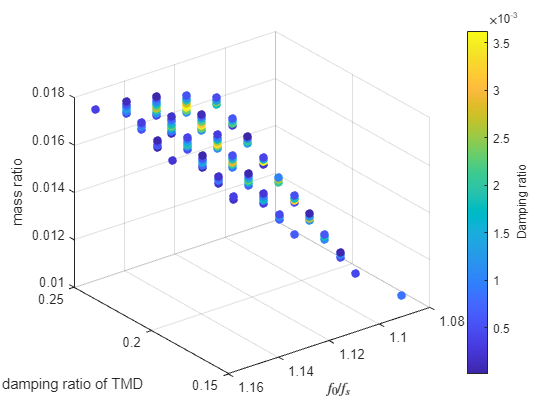

Damping_result_filter=Damping_result(Damping_result.("Min Damping Ratio")>0,:);
Damping_result_filter=Damping_result_filter(Damping_result_filter.("Mass Ratio")<=0.03,:);
Frequency = Damping_result_filter.("Frequency TMD");                              % longitude data
DampingRatio =Damping_result_filter.("Damping Ratio");                                % latitude data
MassRatio = Damping_result_filter.("Mass Ratio");                       % percent rural data
MinDampingRatio =Damping_result_filter.("Min Damping Ratio");                        % fatalities data
Fre0=0.833853594612216;
Damping_result_filter.("Fre_ratio")=Frequency./Fre0;
scatter3(Damping_result_filter.("Fre_ratio"),DampingRatio,MassRatio,40,MinDampingRatio,'filled')    % draw the scatter plot
ax = gca;
ax.XDir = 'reverse';
% view(-31,14)
xlabel('$f_0 / f_s$','Interpreter','latex')
ylabel('damping ratio of TMD')
zlabel('mass ratio')

cb = colorbar;                                     % create and label the colorbar
cb.Label.String = 'Damping ratio';

数据分析

[~,maxseq]=max(MinDampingRatio);%最大阻尼比对应参数
maxresult=Damping_result(maxseq,:);
% idx=Damping_result.("Damping Ratio")<=0.2;
% data_filter=Damping_result(idx,:);
data_filter=Damping_result;
idx=data_filter.("Mass Ratio")==0.015;
data_filter=data_filter(idx,:);
[~,maxseq2]=max(data_filter.("Min Damping Ratio"));%最大阻尼比对应参数
maxresult2=data_filter(maxseq2,:);
disp(maxresult2)

    Frequency TMD    Damping Ratio    Mass Ratio    Frequency1    Frequency 2    Frequency 3    Damping Ratio 1    Damping Ratio 2    Damping Ratio 3    Min Damping Ratio
    _____________    _____________    __________    __________    ___________    ___________    _______________    _______________    _______________    _________________

        0.93             0.22           0.015        0.81896        0.84211        0.99809         0.0049167          0.0012389           0.17845            0.0012389    




Damping_result_filter_data=table2array(Damping_result_filter);

% save Dampingresult_filter_data_1036_1mode Damping_result_filter_data